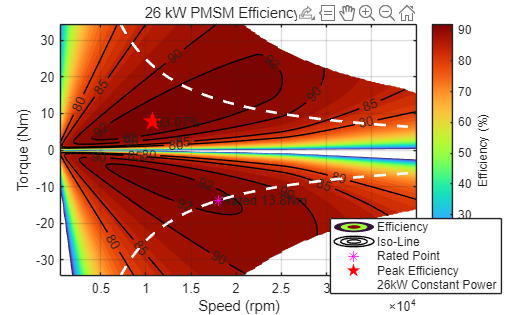

clc; clear; close all;

%% =====================================================
% PMSM Parameters (永磁同步电机参数)
%% =====================================================
p = 2;              % 极对数 (Pole pairs)
Rs = 12.45e-3;      % 定子相电阻 (Stator resistance) [Ohm]
Ld = 38.2e-6;       % d轴电感 (d-axis inductance) [H]
Lq = 46.3e-6;       % q轴电感 (q-axis inductance) [H]
psi_f = 28.67e-3;   % 永磁体磁链 (PM flux linkage) [Wb]

%% DC Bus (直流母线参数)
Vdc = 270;          % 直流母线电压 (DC bus voltage) [V]
m_max = 0.95;       % 最大调制比 (Max modulation index)，考虑死区等裕量
% 逆变器能输出的最大相电压幅值 (SVPWM线性区)
Vmax = Vdc / sqrt(3) * m_max; 

%% Rated Machine (电机额定参数)
Pn = 26e3;          % 额定功率 (Rated power) [W]
P_max = 75e3;       % 最高功率 (Rated power) [W]
n_rated = 18000;    % 额定转速 (Rated speed) [rpm]
n_max = 40000;      % 最高转速 (Max speed) [rpm]
% 额定转矩推导: T = P / (omega)
T_rated = Pn / (2 * pi * n_rated / 60); 
T_max = 35;         % 峰值转矩限制 [Nm]

%% Current Limit (电流限制)
Imax = 400;         % 最大相电流峰值限制 [A]

%% Grid (网格生成：用于遍历所有转速和转矩工况点)
speed_vec = linspace(500, n_max, 160);      % 转速向量
% torque_vec = linspace(0.5, T_max, 120);     % 转矩向量
torque_vec = linspace(-T_max, T_max, 240);
[N, T] = meshgrid(speed_vec, torque_vec);   % 生成网格坐标
ETA = nan(size(N));                         % 初始化效率矩阵为 NaN

%% Loss Coefficients (损耗系数)
Kh = 0.05;          % 磁滞损耗系数 (Hysteresis loss coeff)
Ke = 1.5e-5;        % 涡流损耗系数 (Eddy current loss coeff)
Kfw = 8e-8;         % 风阻损耗系数 (Windage loss coeff)

%% =====================================================
% Calculation (效率计算核心循环)
%% =====================================================
for k = 1:numel(N)
    n = N(k);                   % 当前工况转速 [rpm]
    wm = 2 * pi * n / 60;       % 机械角速度 (Mechanical angular velocity) [rad/s]
    we = p * wm;                % 电角速度 (Electrical angular velocity) [rad/s]
    Tref = T(k);                % 当前工况目标转矩 [Nm]

    %% MTPA (最大转矩电流比控制)
    % 求解在当前目标转矩下，最优的 d、q 轴电流
    [Id, Iq] = mtpaCurrent(Tref, p, psi_f, Ld, Lq);

    %% Current Limit (电流限制检查)
    Is = hypot(Id, Iq);         % 定子电流幅值: sqrt(Id^2 + Iq^2)
    if Is > Imax
        continue;               % 超过电流极限，该工况点不可达，跳过
    end

    %% Voltage Circle (计算当前电流下的稳态电压)
    Vd = Rs * Id - we * Lq * Iq;
    Vq = Rs * Iq + we * (Ld * Id + psi_f);
    Vs = hypot(Vd, Vq);         % 定子电压幅值

    %% Weakening (弱磁控制区)
    % 如果计算出的电压超过了逆变器极限，则需要增加负向 Id 进行弱磁
    if Vs > Vmax
        % 定义弱磁电压误差函数 (目标是让电压幅值等于 Vmax)
        FW = @(id) hypot(Rs * id - we * Lq * Iq, Rs * Iq + we * (Ld * id + psi_f)) - Vmax;
        try
            % 在 [-Imax, 0] 范围内寻找使电压等于 Vmax 的负 Id
            Id_fw = fzero(FW, [-Imax 0]); 
        catch
            continue; % 如果找不到解，说明该点在电压极限椭圆外，不可达
        end
        Id = Id_fw;
        Is = hypot(Id, Iq);
        
        % 再次检查弱磁后的电流是否超限
        if Is > Imax
            continue;
        end
    end

    %% Electromagnetic Torque (电磁转矩重新确认)
    Te = 1.5 * p * (psi_f * Iq + (Ld - Lq) * Id * Iq);

    %% Power and Losses (功率与损耗计算)
    Pout = Te * wm;                         % 输出机械功率
    if abs(Pout) > P_max  % 如果计算出的输出功率超过了电机的峰值/额定功率上限
        continue; % 该点在物理上无法持续运行，剔除
    end
    Pcu = 3 * Rs * (Id^2 + Iq^2);           % 铜耗 (Copper loss)
    Pfe = Kh * we + Ke * we^2;              % 铁耗 (Iron loss)
    Pfw = Kfw * wm^3;                       % 风阻损耗 (Windage loss)
    % Pstray = 0.005 * Pout;                  % 杂散损耗 (Stray loss)
    % 杂散损耗通常与实际传递的功率绝对值成正比
    Pstray = 0.005 * abs(Pout);
    
    Ploss = Pcu + Pfe + Pfw + Pstray;       % 总损耗
    % eta = Pout / (Pout + Ploss);            % 效率
    %% 引入四象限效率判断逻辑
    if Pout > 0 
        % 电动模式 (Motoring)
        eta = Pout / (Pout + Ploss);
    else 
        % 发电模式 (Generating/Regen)
        P_mech_in = abs(Pout);              % 输入的机械功率
        P_elec_out = P_mech_in - Ploss;     % 扣除损耗后输出给电池的电功率
        
        if P_elec_out <= 0
            eta = 0;                        % 损耗大于输入，发不出电，效率设为0
        else
            eta = P_elec_out / P_mech_in;
        end
    end
    
    ETA(k) = eta * 100;                     % 转换为百分比并存入矩阵
end

% 寻找哪些行至少包含一个有效的效率值（非 NaN）
valid_rows = any(~isnan(ETA), 2); 

% 仅保留包含有效数据的行，彻底扔掉上方的空白无用网格
N = N(valid_rows, :);
T = T(valid_rows, :);
ETA = ETA(valid_rows, :);
%% =====================================================
% Plot (绘图生成效率 Map)
%% =====================================================
figure('Color', 'w');
% 绘制效率等高线填充图
contourf(N, T, ETA, 10:2:98, 'LineColor', 'none'); 
hold on;

% 绘制特定效率值的黑色等高线并标注数值
[c, h] = contour(N, T, ETA, [80 85 90 92 94 95 96 97], 'k');
clabel(c, h);

colormap(turbo);
cb = colorbar;
cb.Label.String = 'Efficiency (%)';
xlabel('Speed (rpm)');
ylabel('Torque (Nm)');
title('26 kW PMSM Efficiency Map');
grid on;

%% 绘制额定工作点
plot(n_rated, -T_rated, 'm*', 'MarkerFaceColor', 'm', 'MarkerSize', 8);
text(n_rated, -T_rated, sprintf(' Rated %.1fNm', T_rated));

%% 寻找并绘制最高效率点
[maxEta, idx] = max(ETA(:));
[r, c] = ind2sub(size(ETA), idx);
plot(N(r,c), T(r,c), 'rp', 'MarkerFaceColor', 'r', 'MarkerSize', 14);
text(N(r,c), T(r,c), sprintf(' %.2f%%', maxEta));

%% 绘制恒功率曲线 (等功率线)
% Tcp = Pn ./ (2 * pi * speed_vec / 60);
% Tcp(Tcp > T_max) = nan;
% plot(speed_vec, Tcp, 'w--', 'LineWidth', 2);
%% 修改为绘制上下两条线：
Tcp_motor = Pn ./ (2 * pi * speed_vec / 60);
Tcp_motor(Tcp_motor > T_max) = nan; 
plot(speed_vec, Tcp_motor, 'w--', 'LineWidth', 2);

Tcp_gen = -Pn ./ (2 * pi * speed_vec / 60); % 负功率边界
Tcp_gen(Tcp_gen < -T_max) = nan;            % 注意这里是小于负的最大扭矩
plot(speed_vec, Tcp_gen, 'w--', 'LineWidth', 2);

legend('Efficiency', 'Iso-Line', 'Rated Point', 'Peak Efficiency', ...
    '26kW Constant Power', 'Location', 'southeast');



%% =====================================================
% 辅助函数: MTPA 算法
% 给定目标转矩，计算出产生该转矩且电流最小的 Id, Iq
%% =====================================================
function [Id, Iq] = mtpaCurrent(T, p, psi_f, Ld, Lq)
    % 构造转矩方程（将 Id 用 Iq 表达出来代入转矩公式）
    % 目标是求解出能产生指定转矩 T 的 Iq
    torqueFun = @(iq) 1.5 * p * (psi_f * iq + (Ld - Lq) * ...
        (psi_f / (2 * (Lq - Ld)) - sqrt((psi_f / (2 * (Lq - Ld)))^2 + iq.^2)) .* iq) - T;
    
    % 数值求解 Iq
    % Iq = fzero(torqueFun, [0 1000]);
    Iq = fzero(torqueFun, [-1000 1000]);
    
    % 根据求解出的 Iq 计算对应的最优负向 Id
    Id = psi_f / (2 * (Lq - Ld)) - sqrt((psi_f / (2 * (Lq - Ld)))^2 + Iq^2);
end
